# Data Preparation

clc
clear all
close all
rng(0)

## Induction Machine (IM)

IM = struct();

Nominal values and structural parameters

Converter control designed to operate with 50% nominal torque and 50% nominal speed

IM.VLLN  = 380;  % [V] Line-line rms rated stator voltage
IM.PN    = 3000; % [W] Rated active power
IM.FPn   = 0.81; % Rated power factor
IM.SN    = IM.PN / IM.FPn; % [VA] Rated apparent power
IM.fN    = 50;             % [Hz] Rated stator frequency
IM.f_max = IM.fN * 0.5;    % [Hz] Max. stator frequency
IM.wN    = 1450 * pi / 30; % [rad/s] Rated rotor speed
IM.w_max = IM.wN * 0.5;    % [rad/s] Max. rotor speed
IM.IN    = IM.SN / (IM.VLLN * sqrt(3)); % [A] Rms rated stator current
IM.TN    = IM.PN / IM.wN;               % [Nm] Rated electrical torque
IM.FrN   = sqrt(2/3) * IM.VLLN / (2 * pi * IM.fN); % [Wb] Rated rotor flux
IM.np    = 2; % Number of pole pairs

Lumped parameters

IM.J    = 0.006;    % [kg/m^2] Rotor inertia 
IM.Rs   = 1.8;      % [Ohm] Stator resistance
IM.Rr   = 1.8;      % [Ohm] Equivalent rotor resistance
IM.Los  = 2.6e-3;   % [H] Stator leakage inductance
IM.Lor  = 2.6e-3;   % [H] Rotor leakage inductance
IM.Lm   = 235.1e-3; % [H] Mutual inductance
IM.Ls   = IM.Los + IM.Lm; % [H] Stator inductance
IM.Lr   = IM.Lor + IM.Lm; % [H] Rotor inductance

IM.kr    = IM.Lm / IM.Lr;
IM.ks    = IM.Lm / IM.Ls;
IM.tau_r = IM.Lr / IM.Rr;
IM.o     = 1 - IM.ks * IM.kr;
IM.Ro    = IM.Rs + IM.Rr * IM.kr^2;
IM.Lo    = IM.o * IM.Ls;
IM.tau_o = IM.Lo / IM.Ro;
IM.kT    = 1.5 * IM.np * IM.kr;

IM.isdN  = IM.FrN / IM.Lm;
IM.isqN  = IM.TN / (3/2*IM.np*IM.kr*IM.FrN);

## Modular Multilevel Converter (M2C)

M2C = struct(); % Modular Multilevel Converter parameters

Parameters

M2C.ax     = [1, 1, 1, 0, 0, 0;         % Input incidence matrix
              0, 0, 0, 1, 1, 1];
M2C.ay     = [1, 0, 0, 1, 0, 0;         % Output incidence matrix
              0, 1, 0, 0, 1, 0;
              0, 0, 1, 0, 0, 1];
M2C.p      = size(M2C.ax, 1);           % # of input ports
M2C.q      = size(M2C.ay, 1);           % # of output ports
M2C.A      = [M2C.ax;                   % Incidence matrix
             -M2C.ay];
M2C.m      = size(M2C.A, 2);            % # of clusters
M2C.pinvA  = pinv(M2C.A);               % Incidence matrix inverse
M2C.N      = null(M2C.A, 'rational');   % Nullspace matrix
M2C.n      = size(M2C.N, 2);            % # of LICCs (Linearly Independent Circulating Currents)
M2C.pinvN  = pinv(M2C.N);               % Nullspace matrix inverse
M2C.Rb     = 0.2;                       % [Ohm] Branch resistance
M2C.Lb     = 5e-3;                      % [H] Branch inductance
M2C.Csm    = 987e-6;                    % [F] Submodule capacitance
M2C.Nsm    = 4;                         % # of submodules per cluster
M2C.C      = M2C.Csm / M2C.Nsm;         % [F] Equivalent branch capacitance
M2C.As     = -eye(M2C.m)*M2C.Rb/M2C.Lb; % Cluster current model continuous state matrix
M2C.Bs     = -eye(M2C.m)/M2C.Lb;        % Cluster current model continuous input matrix
M2C.Vdc    = 520;                       % [V] DC-link voltage
M2C.Ax_max = M2C.Vdc / 2;               % Max. input voltage
M2C.Ay_max = sqrt(2/3)*IM.VLLN*IM.w_max/IM.wN + IM.Rs*IM.IN; % Max. output voltage (50% machine's nominal speed)
M2C.ix_max = 4.2;                       % Max. input current
M2C.iy_max = sqrt(IM.isdN^2+(0.5*IM.isqN)^2); % Max. output current
M2C.is_max = 8.5;                       % Max. branch current
M2C.Vc_ref = 520;                       % Cluster capacitor voltage reference
M2C.vo_max = M2C.Vc_ref - M2C.Ax_max;   % Max. CMV at zero machine speed
M2C.Ec_ref = M2C.C / 2 * M2C.Vc_ref^2;  % Cluster energy reference
M2C.vc_ref = M2C.Vc_ref / M2C.Nsm;      % Submodule capacitor voltage reference
M2C.vc_dev = 0.15;                      % [pu] Max. capacitor voltage deviation from reference
M2C.vc_m_dev = 10/M2C.Vc_ref;           % [pu] Max. cap. voltage MEAN deviation from reference
M2C.Ec_dev = ((1+M2C.vc_dev)^2 - 1);    % [pu] Max. cap. energy deviation from reference

# Load data

m = M2C.m;
n = M2C.n;

From random data generator

buffer_name       = 'train100k';
buffer_train      = load(strcat(['ImitationLearningSimulink\TrainingData\Data\', buffer_name, '.mat']), 'buffer').buffer;
buffer_validation = load('ImitationLearningSimulink\TrainingData\Data\validation.mat', 'buffer').buffer;

From expert sample

S1 = load('ImitationLearningSimulink\TrainingData\Data\expert_sample_clean1.mat').sample;
X1 = S1.net_in;
Y1 = S1.mpc_out;

S2 = load('ImitationLearningSimulink\TrainingData\Data\expert_sample_noisy1.mat').sample;
X2 = S2.net_in;
Y2 = S2.mpc_out;

S3 = load('ImitationLearningSimulink\TrainingData\Data\expert_sample_clean2.mat').sample;
X3 = S3.net_in;
Y3 = S3.mpc_out;

S4 = load('ImitationLearningSimulink\TrainingData\Data\expert_sample_noisy2.mat').sample;
X4 = S4.net_in;
Y4 = S4.mpc_out;

S5 = load('ImitationLearningSimulink\TrainingData\Data\expert_sample_clean3.mat').sample;
X5 = S5.net_in;
Y5 = S5.mpc_out;

S6 = load('ImitationLearningSimulink\TrainingData\Data\expert_sample_noisy3.mat').sample;
X6 = S6.net_in;
Y6 = S6.mpc_out;

S7 = load('ImitationLearningSimulink\TrainingData\Data\dagger1.mat').sample;
X7 = S7.net_in;
Y7 = S7.mpc_out;

S8 = load('ImitationLearningSimulink\TrainingData\Data\dagger2.mat').sample;
X8 = S8.net_in;
Y8 = S8.mpc_out;

XS = [X1, X2, X3, X4, X5, X6, X7, X8];
YS = [Y1, Y2, Y3, Y4, Y5, Y6, Y7, Y8];

buffer_train.X = [buffer_train.X, XS];
buffer_train.Y = [buffer_train.Y, YS];
% buffer_train.X = XS;
% buffer_train.Y = YS;

Complete buffer

buffer_train

buffer_train = struct with fields:
    X: [14×186408 double]
    Y: [3×186408 double]


buffer_validation

buffer_validation = struct with fields:
    X: [14×1000 double]
    Y: [3×1000 double]



buffer   = struct();
buffer.X = [buffer_train.X, buffer_validation.X];
buffer.Y = [buffer_train.Y, buffer_validation.Y];

X = buffer.X;
Y = buffer.Y;

Ninputs  = size(X, 1)

Ninputs = 14

Noutputs = size(Y, 1)

Noutputs = 3


figure
subplot(4, 2, 1)              % Ec-mean(Ec)
histogram(X(1:m, :), 100)
title('$\mathbf{E}_C-\bar{E}_C$', 'Interpreter', 'latex')
subplot(4, 2, 2)              % iP
histogram(X(m+1, :), 100)
title('$i_P$', 'Interpreter', 'latex')
subplot(4, 2, 3)              % im
histogram(X(m+2:m+3, :), 100)
title('$i_{m\alpha\beta}$', 'Interpreter', 'latex')
subplot(4, 2, 4)              % vm
histogram(X(m+4:m+5, :), 100)
title('$v_{m\alpha\beta}$', 'Interpreter', 'latex')
subplot(4, 2, 5)              % pm
histogram(X(m+6, :), 100)
title('$p_m$', 'Interpreter', 'latex')
subplot(4, 2, 6)              % qm
histogram(X(m+7, :), 100)
title('$q_m$', 'Interpreter', 'latex')
subplot(4, 1, 4)              % wy
histogram(X(m+8, :), 100)
title('$w_y$', 'Interpreter', 'latex')
sgtitle('Input data distributions')

% subplot(5, 2, 9)              % ie_ref_OS
% histogram(X(m+9:m+10, :), 100)
% title('$i_e OS$', 'Interpreter', 'latex')
% sgtitle('Input data distributions')
% subplot(5, 2, 10)              % vo_ref_OS
% histogram(X(m+11, :), 100)
% title('$v_o OS$', 'Interpreter', 'latex')
% sgtitle('Input data distributions')
 
figure
subplot(1, 2, 1)          % ie
histogram(Y(1:n, :), 100)
title('$i_\varepsilon$', 'Interpreter', 'latex')
subplot(1, 2, 2)          % vo
histogram(Y(end, :), 100)
title('$v_o$', 'Interpreter', 'latex')
sgtitle('Output data distributions')

## Input limits

Xmax = zeros(Ninputs, 1);

% Fixed variables
Xmax(1:m)     = M2C.Ec_ref * ((1+M2C.vc_dev)^2 - 1);
Xmax(m+1)     = M2C.ix_max;

% Machine alpha-beta variables
Xmax(m+2:m+3) = M2C.iy_max;
Xmax(m+4:m+5) = M2C.Ay_max;
Xmax(m+6:m+7) = 3/2 * M2C.Ay_max * M2C.iy_max;

% % Machine line variables
% Xmax(m+2:m+3) = M2C.iy_max;
% Xmax(m+4:m+5) = M2C.Ay_max * sqrt(3);
% Xmax(m+6:m+7) = sqrt(3) * M2C.Ay_max * M2C.iy_max;

% Optional variable
Xmax(m+8) = IM.f_max * 2*pi;
% Xmax(m+9) = 1;

% % Additional variables
% Xmax(m+9:m+10) = M2C.is_max;
% Xmax(m+11)     = M2C.vo_max;

## Output limits

- ie  (n)

- vo (1)

Ymax = zeros(Noutputs, 1);
Ymax(1:2) = M2C.is_max;
Ymax(3)   = M2C.vo_max;

save('ImitationLearningSimulink\TrainingData\Data\Xmax.mat', 'Xmax')
save('ImitationLearningSimulink\TrainingData\Data\Ymax.mat', 'Ymax')

# Preprocessing

Input/output sizes

size(X)

ans =           14      187408


size(Y)

ans =            3      187408


Normalization

X = X ./ Xmax;
Y = Y ./ Ymax;

Training/validation split

X_tr  = buffer_train.X ./ Xmax;
Y_tr  = buffer_train.Y ./ Ymax;
X_val = buffer_validation.X ./ Xmax;
Y_val = buffer_validation.Y ./ Ymax;

Data augmentation with white noise

% X_tr = [X_tr, X_tr+0.01*randn(size(X_tr))];
% Y_tr = [Y_tr, Y_tr];

Transform to dlarray

dlX     = dlarray(X, 'CB');
dlY     = dlarray(Y, 'CB');
dlX_tr  = dlarray(X_tr, 'CB');
dlY_tr  = dlarray(Y_tr, 'CB');
dlX_val = dlarray(X_val, 'CB');
dlY_val = dlarray(Y_val, 'CB');
dsX_tr  = arrayDatastore(dlX_tr, 'IterationDimension', 2);
dsY_tr  = arrayDatastore(dlY_tr, 'IterationDimension', 2);
dsXY_tr = combine(dsX_tr, dsY_tr);

# Exploratory data analysis

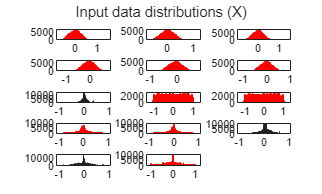

n_cols = 3;

figure
for idx = 1:Ninputs
    subplot(ceil(Ninputs / n_cols), n_cols, idx);
    if max(abs(X(idx, :))) > 1
        histogram(X(idx, :), 100, 'FaceColor', 'red', 'EdgeColor', 'red');
    else
        histogram(X(idx, :), 100);
    end
end
sgtitle('Input data distributions (X)')

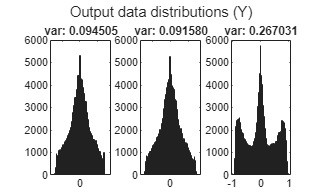


figure
for idx = 1:Noutputs
    subplot(ceil(Noutputs / n_cols), n_cols, idx)
    if max(abs(Y(idx, :))) > 1
        histogram(Y(idx, :), 100, 'FaceColor', 'red', 'EdgeColor', 'red')
    else
        histogram(Y(idx, :), 100)
    end
    title(sprintf('var: %f', var(Y(idx, :))))
end
sgtitle('Output data distributions (Y)')

# Dimensionality reduction for state space visualization

## PCA

Input

% [coeff, score, latent] = pca(X');
% 
% figure
% subplot(1, 2 ,1)
% scatter(score(:, 1), score(:, 2), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('2D');
% xlabel('pca_1');
% ylabel('pca_2');
% 
% subplot(1, 2, 2)
% scatter3(score(:, 1), score(:, 2), score(:, 3), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('3D');
% xlabel('pca_1');
% ylabel('pca_2');
% zlabel('pca_3');
% 
% sgtitle('PCA X')

Output

% [coeff, score, latent] = pca(Y');
% 
% figure
% subplot(1, 2, 1)
% scatter(score(:, 1), score(:, 2), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('2D');
% xlabel('pca_1');
% ylabel('pca_2');
% 
% subplot(1, 2, 2)
% scatter3(score(:, 1), score(:, 2), score(:, 3), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('3D');
% xlabel('pca_1');
% ylabel('pca_2');
% zlabel('pca_3');
% 
% sgtitle('PCA Y')

## Clustering

% n_clusters = 5; % Número de clusters
% epsilon = 0.1;  % Radio máximo para DBSCAN
% minPts = 5;     % Mínimo número de puntos para DBSCAN
% 
% % K-means
% [idx_kmeans, C_kmeans] = kmeans(Y', n_clusters, 'Replicates', 10);
% 
% % DBSCAN
% idx_dbscan = dbscan(Y', epsilon, minPts);
% 
% % GMM
% gmm = fitgmdist(Y', n_clusters, 'RegularizationValue', 1e-5);
% idx_gmm = cluster(gmm, Y');
% 
% % PCA
% num_dims = 3;
% [coeff, score, latent] = pca(Y');
% X_reduced = score(:, 1:num_dims);
% 
% figure
% 
% % K-means
% subplot(1, 3, 1)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_kmeans, 'filled');
% title('K-means'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% % DBSCAN
% subplot(1, 3, 2)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_dbscan, 'filled');
% title('DBSCAN'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% % GMM
% subplot(1, 3, 3)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_gmm, 'filled');
% title('GMM'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% sgtitle('Clustering in Original Space');

## UMAP

% pyenv('Version', '3.12', 'ExecutionMode', 'OutOfProcess')
% system('pip install umap-learn')
% code = [
%         "import sys, subprocess"
%         'cmd = [sys.executable, "-m", "pip", "install", "umap-learn"]'
%         "subprocess.check_call(cmd)"
%        ];
% code = strjoin(code, newline);
% pyrun(code)

2D

% code =  [
%           "import umap"
%           "import numpy as np"
%           "reducer = umap.UMAP(n_neighbors=15, min_dist=0.001, n_components=2)"
%           "Xumap = reducer.fit_transform(np.transpose(X))"
%         ];
% 
% code = strjoin(code, newline);
% 
% Xumap = double(pyrun(code, 'Xumap', X=X));
% Yumap = double(pyrun(code, 'Xumap', X=Y));
% 
% figure;
% subplot(1, 2, 1);
% scatter(Xumap(:, 1), Xumap(:, 2), 1, 'filled');
% colormap(jet);
% title('UMAP X');
% xlabel('umap_1'); ylabel('umap_2'); grid on;
% 
% subplot(1, 2, 2);
% scatter(Yumap(:, 1), Yumap(:, 2), 1, 'filled');
% colormap(jet);
% title('UMAP Y');
% xlabel('umap_1'); ylabel('umap_2'); grid on;

3D

% code =  [
%           "import umap"
%           "import numpy as np"
%           "reducer = umap.UMAP(n_neighbors=15, min_dist=0.001, n_components=3)"
%           "Xumap = reducer.fit_transform(np.transpose(X))"
%         ];
% 
% code = strjoin(code, newline);
% 
% Xumap = double(pyrun(code, 'Xumap', X=X));
% Yumap = double(pyrun(code, 'Xumap', X=Y));
% 
% figure;
% subplot(1, 2, 1);
% scatter3(Xumap(:, 1), Xumap(:, 2), Xumap(:, 3), 1, 'filled');
% colormap(jet);
% title('UMAP X');
% xlabel('umap_1'); ylabel('umap_2'); zlabel('umap_3'); grid on;
% 
% subplot(1, 2, 2);
% scatter3(Yumap(:, 1), Yumap(:, 2), Yumap(:, 3), 1, 'filled');
% colormap(jet);
% title('UMAP Y');
% xlabel('umap_1'); ylabel('umap_2'); zlabel('umap_3'); grid on;